# PID TEST DRIVE

#### PID control wrt lidardrone reference frame

clc;
clear all;

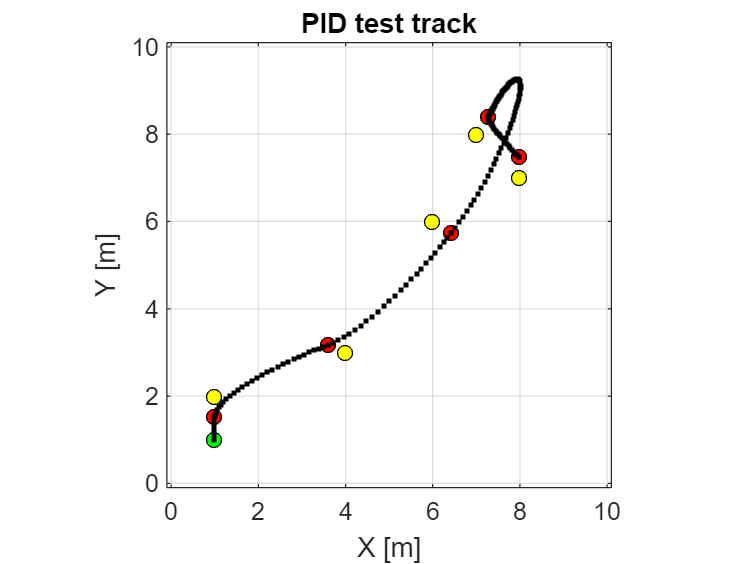


% Coefficienti PID
Kp = 0.5; % componente proporzionale
Ki = 0.05; % componente integrale
Kd = 0.8; % componente derivativa

% Error variables
error_sum=0;
previous_error = 0;

% Posizione iniziale e finale del punto

points = [1, 4, 6, 7, 8; 2, 3, 6, 8, 7];

figure('Name','PID control');
plot(points(1, :), points(2, :), 'o', 'MarkerFaceColor', 'yellow', 'MarkerEdgeColor', 'black')
hold on;
%final_pos = points(:, length(points));
% Velocità iniziale e finale desiderate
initial_vel = [0; 0];
max_speed = [1; 1]; % velocità massima consentita
final_vel = max_speed/2; % velocità finale desiderata
% Simulazione del controllo PID
t = 0; % tempo iniziale
positions = []; % registro delle posizioni per la visualizzazione
% Passo temporale (in secondi)
dt = 0.1;

% Posizione iniziale del punto
pos = points(1, 1);

% Velocità iniziale del punto
vel = initial_vel;

% continua finché non si raggiunge la destinazione

proximity_threshold = 0.5;

for i=1:length(points)
    
    % momentaneous target of the drone where it has to go
    final_pos = points(:, i);
    
    while norm(pos - final_pos) > proximity_threshold  
        % Calcolo dell'errore di posizione
        error_pos = final_pos - pos;
    
        % Componente proporzionale
        control_p = Kp * error_pos;
    
        % Componente integrale
        error_sum = error_sum + error_pos * dt;
        control_i = Ki * error_sum;
    
        % Componente derivativa
        derivative = (error_pos - previous_error) / dt;
        control_d = Kd * derivative;
    
        % Controllo finale
        control = control_p + control_i + control_d;
    
        % Limitazione della velocità
        control = min(max(control, -max_speed), max_speed);
    
        % Aggiornamento della velocità e della posizione
        vel = vel + control * dt;
        pos = pos + vel * dt;
    
        % Memorizzazione della posizione
        positions = [positions, pos];
    
        % Aggiornamento dell'errore precedente
        previous_error = error_pos;
    
        t = t + dt; % incremento del tempo
    end
    
    %Visualize the time requested and error
    % t
    % vel(length(vel))
    % pos(length(pos))
    % error_pos(length(error_pos))
    plot(positions(1, length(positions)), positions(2, length(positions)), 'o', 'MarkerFaceColor', 'r', 'MarkerEdgeColor', 'black');
    %plot the end point
end

% Visualizzazione del percorso
%starting point in red
plot(positions(1, 1), positions(2, 1), 'o', 'MarkerFaceColor', 'g', 'MarkerEdgeColor', 'black');
%plot the path
plot(positions(1, :), positions(2, :), '.', 'Color', 'black');
%ending point in black
grid on;
axis equal; 
xlabel('X [m]');
ylabel('Y [m]');
xlim([-0.10 10 + 0.1]);
ylim([-0.10 10 + 0.1]);
title('PID test track');
hold off